# Loss function surface as a function of P_e and N

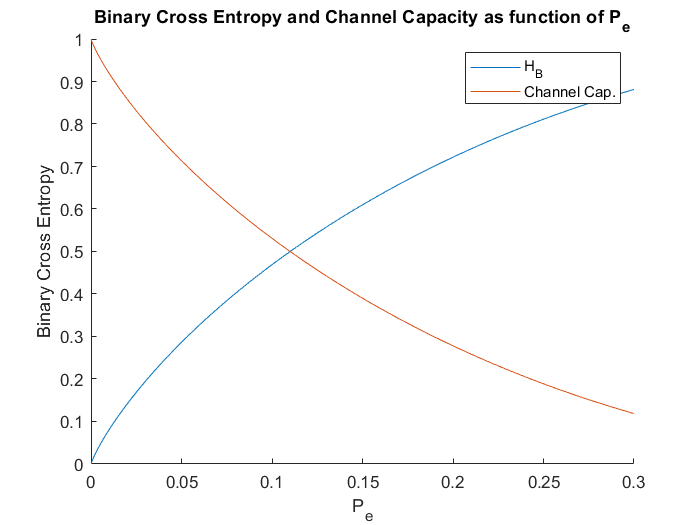

N = 100:100:10000;       %1x100
P_e = 10^-4:10^-4:0.3;  %1x3000

H_B = -(P_e.*log2(P_e) + (1-P_e).*log2(1-P_e));
figure;
hold on;
plot(P_e,H_B, "DisplayName", "H_B");
plot(P_e,1-H_B, "DisplayName", "Channel Cap.");
xlabel("P_e");
ylabel("Binary Cross Entropy");
title("Binary Cross Entropy and Channel Capacity as function of P_e");
legend;

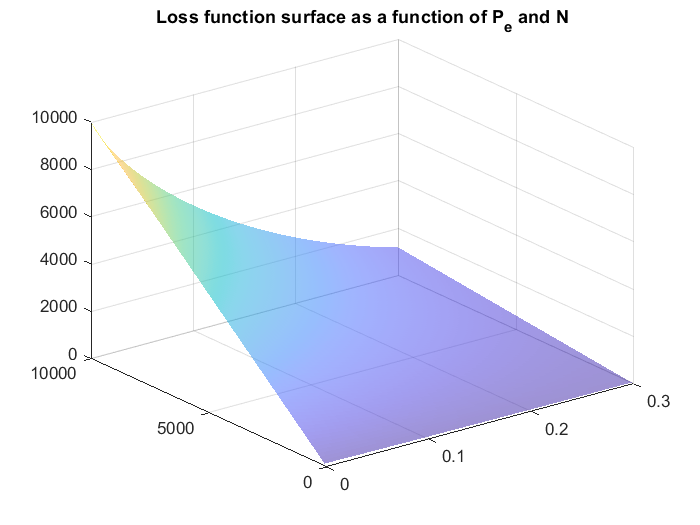


C = 1-H_B;
Theta = N'*C; %100x3000

figure;
% set(gca,'XScale','log');
% set(gca,'YScale','log');
surf(ones(100,1)*P_e, N'*ones(1,length(P_e)), Theta, 'FaceAlpha',0.5,'EdgeColor','none');
title("Loss function surface as a function of P_e and N");

# P_e vs. N for Scheme 3

N_target = [2000];
N_correct = [1995];
amplitude = [19.49];

% Other parameters (only for documentation, do not participate in calculations)
safety_margin = 0.95;
resend_prob = 0.2;

P_e = N_correct./N_target;
